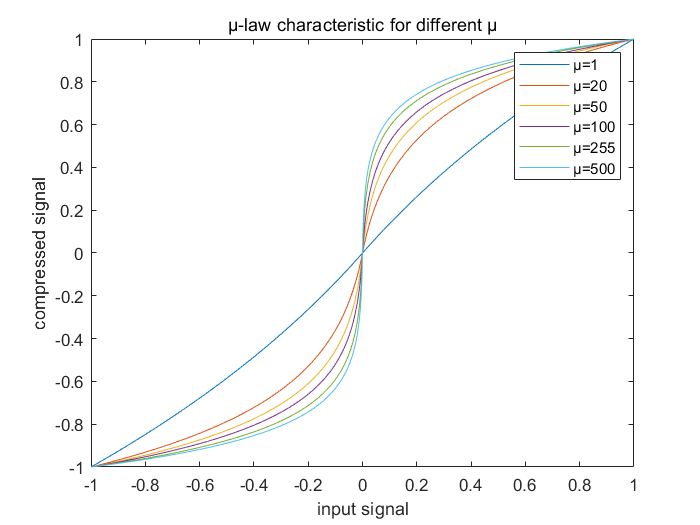

%a
x=-1:0.001:1;
y_1=mulaw(x,1);
y_20=mulaw(x,20);
y_50=mulaw(x,50);
y_100=mulaw(x,100);
y_255=mulaw(x,255);
y_500=mulaw(x,500);

figure;
plot(x,y_1);hold on
plot(x,y_20);hold on
plot(x,y_50);hold on
plot(x,y_100);hold on
plot(x,y_255);hold on
plot(x,y_500);hold on
legend('μ=1','μ=20','μ=50','μ=100','μ=255','μ=500');
title('μ-law characteristic for different μ');
xlabel('input signal');
ylabel('compressed signal');

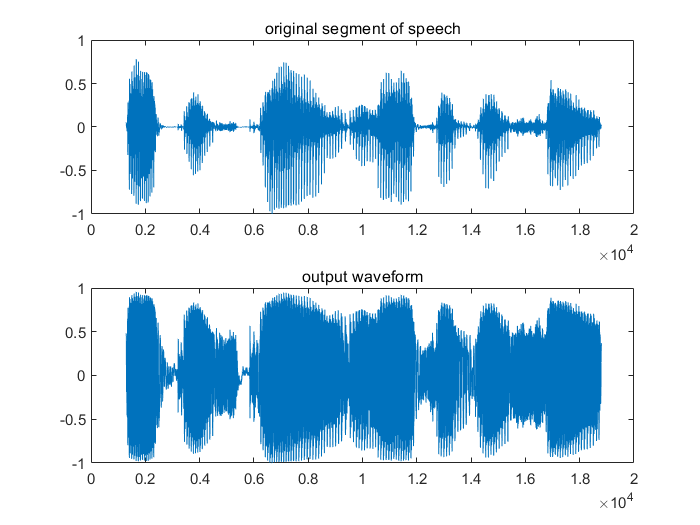


%b
[s,fs]=audioread('s5.wav');
segment=s(1300:18800);
y_segment=mulaw(segment,255);
figure;
subplot(2,1,1);
plot(1300:1:18800,segment);
title('original segment of speech');
subplot(2,1,2);
plot(1300:1:18800,y_segment);
title('output waveform');

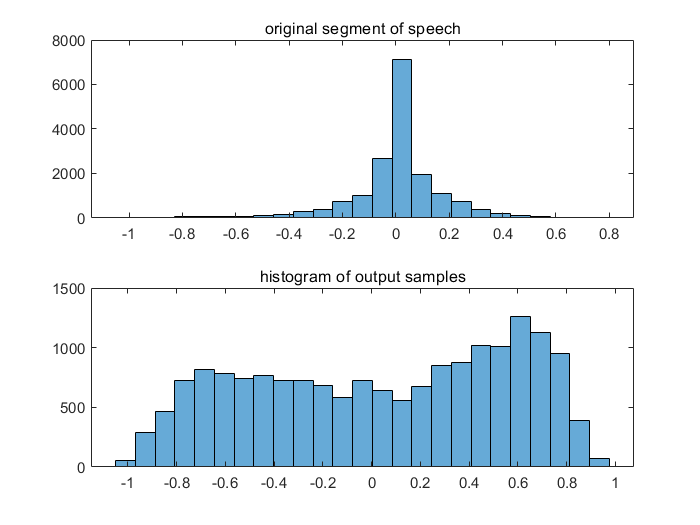


figure;
subplot(2,1,2);
y_hist=histogram(y_segment,25);
title('histogram of output samples');
subplot(2,1,1);
original_hist=histogram(segment,25);
title('original segment of speech');

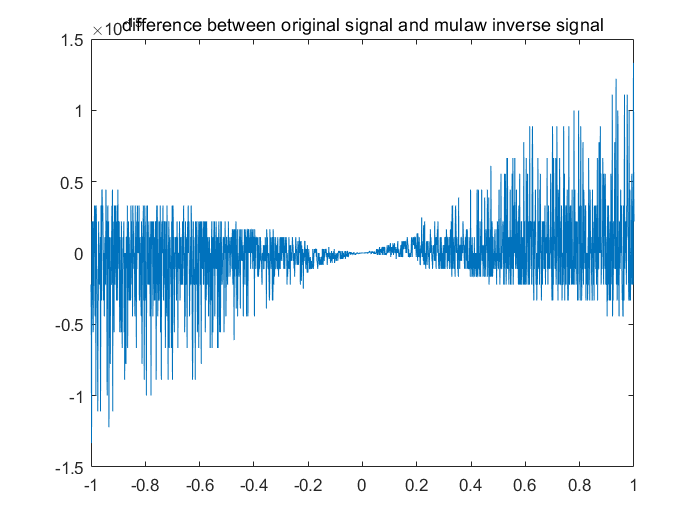


%c
v=mulawinv(mulaw(x,255),255);
figure;
plot(-1:0.001:1,x-v');
title('difference between original signal and mulaw inverse signal');

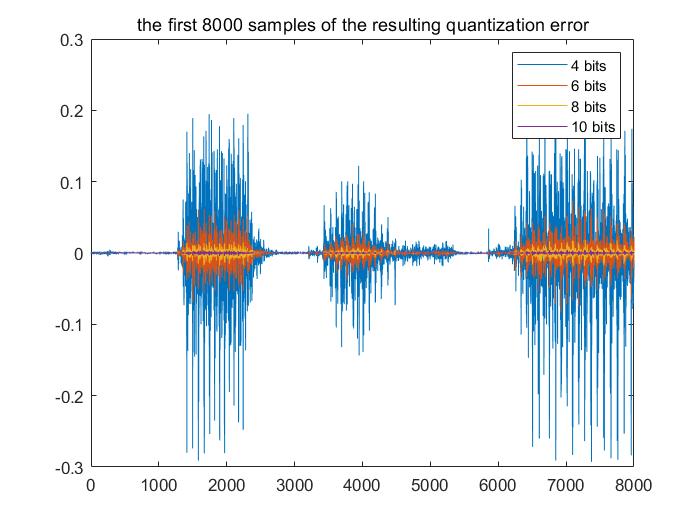


%d

yh_10=fxquant(mulaw(s,255),10,'round','sat');
yh_8=fxquant(mulaw(s,255),8,'round','sat');
yh_6=fxquant(mulaw(s,255),6,'round','sat');
yh_4=fxquant(mulaw(s,255),4,'round','sat');

error_10=mulawinv(yh_10,255)-s;
error_8=mulawinv(yh_8,255)-s;
error_6=mulawinv(yh_6,255)-s;
error_4=mulawinv(yh_4,255)-s;

figure;
plot(error_4(1:8000));hold on;
plot(error_6(1:8000));hold on;
plot(error_8(1:8000));hold on;
plot(error_10(1:8000));hold on;
legend('4 bits','6 bits','8 bits','10 bits');
title('the first 8000 samples of the resulting quantization error');

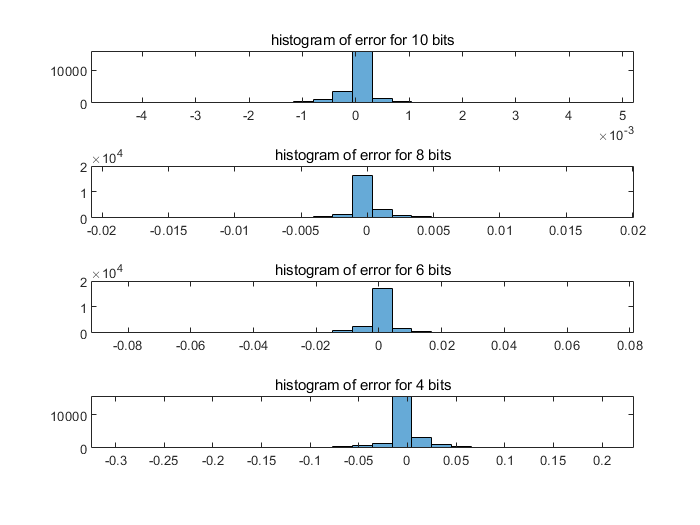


figure
subplot(4,1,1);
error10_hist=histogram(error_10,25);
title('histogram of error for 10 bits');
subplot(4,1,2);
error8_hist=histogram(error_8,25);
title('histogram of error for 8 bits');
subplot(4,1,3);
error6_hist=histogram(error_6,25);
title('histogram of error for 6 bits');
subplot(4,1,4);
error4_hist=histogram(error_4,25);
title('histogram of error for 4 bits');

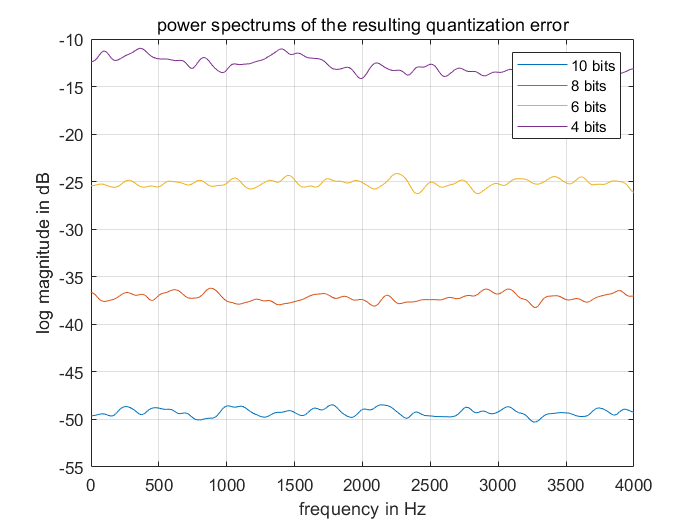


figure
pspect(error_10,fs,1024,128);hold on;
pspect(error_8,fs,1024,128);hold on;
pspect(error_6,fs,1024,128);hold on;
pspect(error_4,fs,1024,128);hold on;
legend('10 bits','8 bits','6 bits','4 bits');
title('power spectrums of the resulting quantization error');